Ageing and Rehabilitation engeneering's Project

clear all
close all
clc

Question and tips:

- Lunghezza windows

- Scelta features (dominio tempi e frequenze)

- Analisi e classificazione su ogni soggetto e tra soggetti diversi

- Mettere i 3 accelerometri insieme e valutare scelte di un accelerometro piuttosto che un altro e/o errori

- Mettere anche ECG e PPG insieme e classificare

Preprocessing part:

IMU on the ankle, ECG on the chest, PPG on the wrist

subject = {"ALE","ALEX","CHIARA","CLAUDIA","DANIELE_PA","ELENA","FEDERICA","FRANCESCO","MATTEO_G","GAETANO","GIORGIA","LUCA","DANIELE_G","MASSIMO","MATTEO_F"};

[indx,tf] = listdlg('ListString',subject);
subject = convertContainedStringsToChars(subject);
sensor = ["IMU","ECG","PPG"];

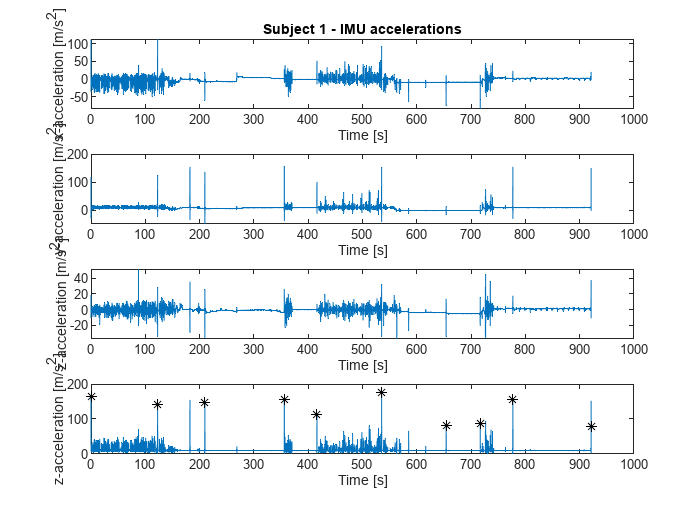

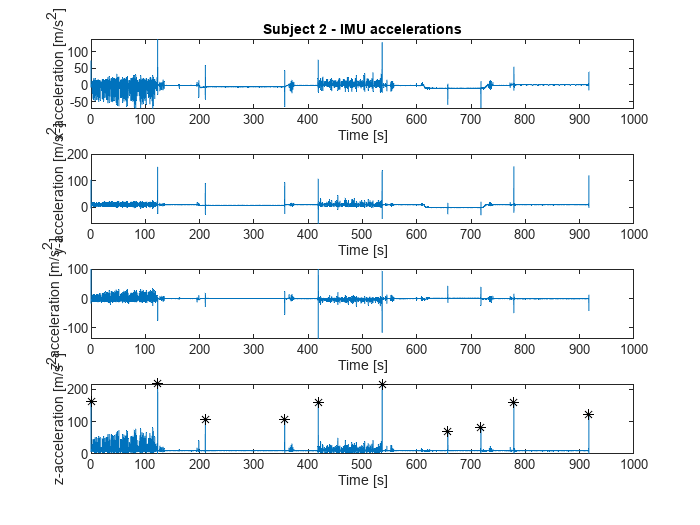

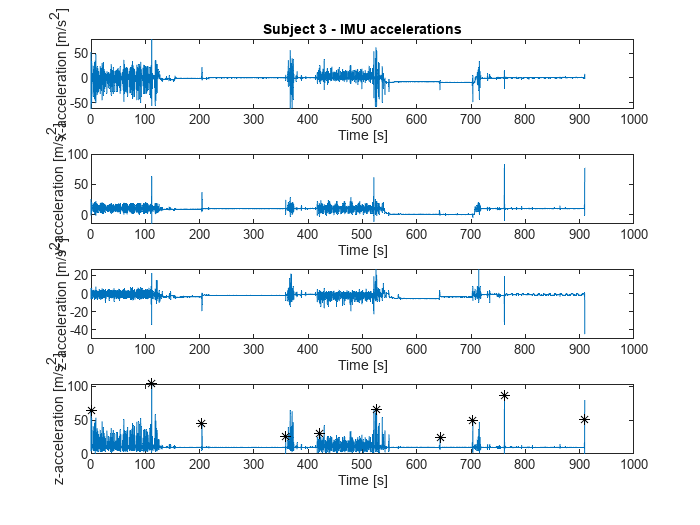

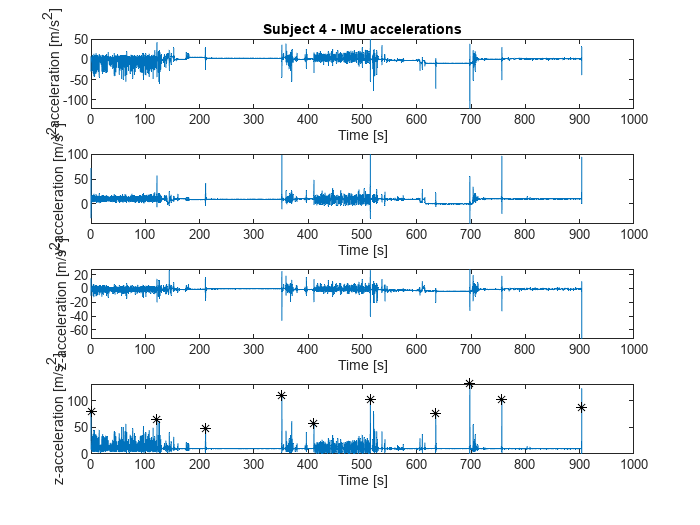

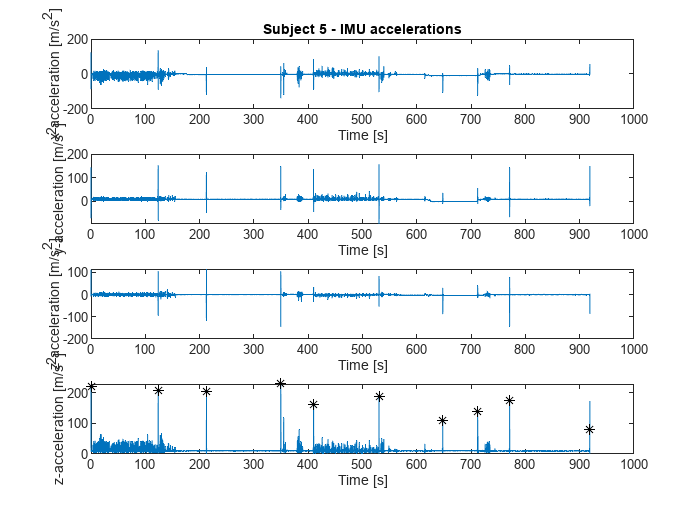

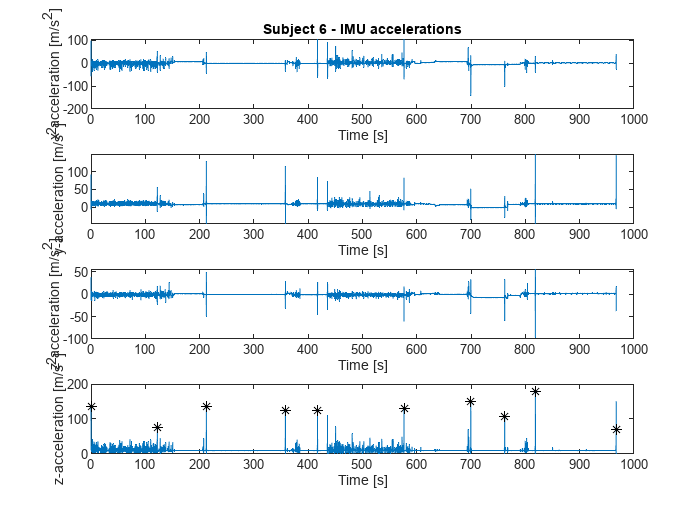

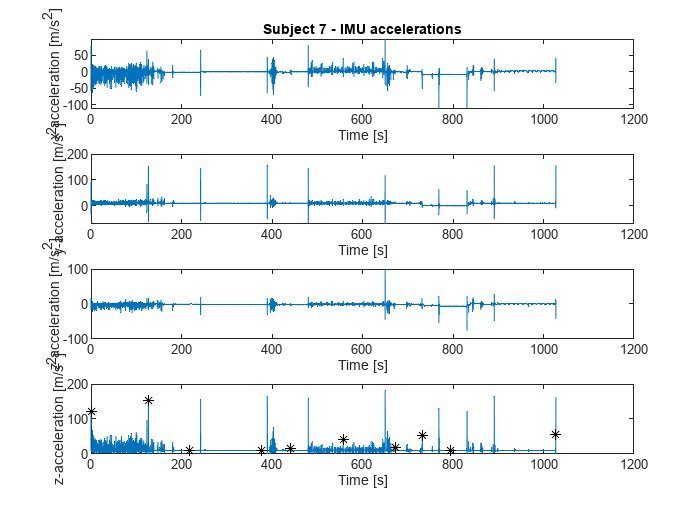

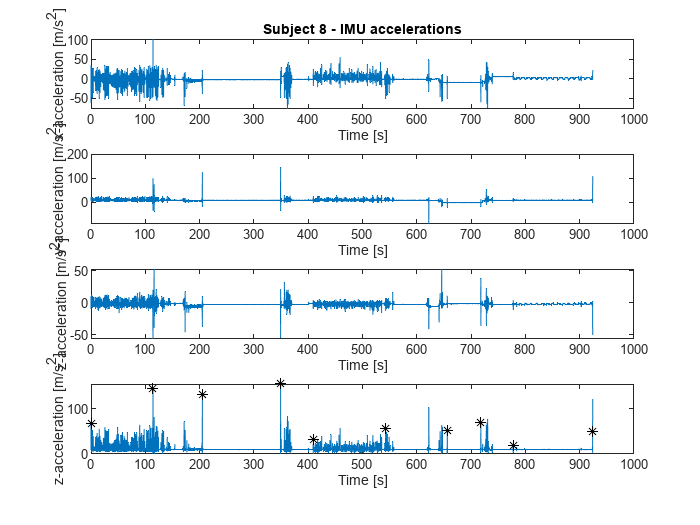

n = length(subject);
for i = 1:n
    for j = 1:3
        stringa = strcat(sensor(j),"_",subject(i),'.mat');
        dati{i,j} = importdata(stringa);
    end
end

FS = 128;

tempi_task = zeros(n,10);

for i = 1:n
    [date_min(i), date_max(i)] = istanteiniziofine(dati{i,1}, dati{i,2}, dati{i,3}, FS, i);
    [dati{i,1}, dati{i,2}, dati{i,3}] = tempo_interesse(dati{i,1}, dati{i,2}, dati{i,3}, date_min(i), date_max(i));
    dati{i,1}.imu_Timestamp_Unix_CAL = [0:length(dati{i,1}.imu_Timestamp_Unix_CAL)-1]/FS;
    dati{i,2}.S_83B4_ECG_Timestamp_Unix_CAL = [0:length(dati{i,2}.S_83B4_ECG_Timestamp_Unix_CAL)-1]/FS;
    dati{i,3}.S_COD4_PPG_Timestamp_Unix_CAL = [0:length(dati{i,3}.S_COD4_PPG_Timestamp_Unix_CAL)-1]/FS;
    tempi_task(i,:) = divisione_task(dati{i,1}, FS, i); % casi particolari per Luca
end


for i = 1:n % Solo per classificazione, non per analisi tra IMU, ECG e PPG
    [dati{i,1}, dati{i,2}, dati{i,3}] = filtraggio(dati{i,1}, dati{i,2}, dati{i,3}, FS);
end

fields = {'S_83B4_ECG_ECG_EMG_Status1_CAL', 'S_83B4_ECG_ECG_EMG_Status2_CAL', 'S_83B4_ECG_ECG_LA_RA_24BIT_CAL', 'S_83B4_ECG_ECG_LL_LA_24BIT_CAL', 'S_83B4_ECG_ECG_LL_RA_24BIT_CAL', 'S_83B4_ECG_ECG_Vx_RL_24BIT_CAL'};

for i = 1:n
    dati_acc{i,1} = dati{i,1};
    dati_acc{i,2} = rmfield(dati{i,2},fields);
    dati_acc{i,3} = rmfield(dati{i,3},"S_COD4_PPG_PPG_A13_CAL");
end

ECG data Extraction

for i = 1:size(dati,1)
    ecg_data = dati{i,2};
    LA_RA = ecg_data.S_83B4_ECG_ECG_LA_RA_24BIT_CAL;
    LL_LA = ecg_data.S_83B4_ECG_ECG_LL_LA_24BIT_CAL;
    LL_RA = ecg_data.S_83B4_ECG_ECG_LL_RA_24BIT_CAL;
    %time_total=datetime(ecg_data.S_83B4_ECG_Timestamp_Unix_CAL,'convertfrom','posixtime','timezone','Europe/Rome');
    time_total = ecg_data.S_83B4_ECG_Timestamp_Unix_CAL;
    val = {[LA_RA LL_LA LL_RA time_total']};
    ECG_SUB{i,1} = val;

    if tempi_task(i,10) > time_total(end)*128
        tempi_task(i,10) = time_total(end)*128;
        kk(i) = i;
    end

    zz = intersect(round(time_total*128,-1),round(tempi_task(i,:),-1));
    time_refe{i,1} = zz;

end

ECG data processing

pause
close all

fps = FS;
fc = 40;
fc_h = 0.1;
[b,a] = butter(3,fc/(fps/2),'low');
[d,c] = butter(3,fc_h/(fps/2),'high');
L = length(subject);

for i = 1:L %size(subject,2)
    LA_RA_n = ECG_SUB{i,1}{1,1}(:,1);
    LL_LA_n = ECG_SUB{i,1}{1,1}(:,2);
    LL_RA_n = ECG_SUB{i,1}{1,1}(:,3);
    time_s = ECG_SUB{i,1}{1,1}(:,4);
    t = time_s(1);
    time_s = (time_s-t)/1000;
    timef = time_s*fps/1000;
    LA_RA_n = LA_RA_n-mean(LA_RA_n);
    LL_LA_n = LL_LA_n-mean(LL_LA_n);
    LL_RA_n = LL_RA_n-mean(LL_RA_n);
    Len = length(time_s);
    
    %LL_RA=detrend(LL_RA(1:10*fps));
    
    for j = 10*fps:10*fps:Len-2*fps
        LL_RA_n(j+1-10*fps:j) = detrend(LL_RA_n(j+1-10*fps:j));
        LL_LA_n(j+1-10*fps:j) = detrend(LL_LA_n(j+1-10*fps:j));
        LA_RA_n(j+1-10*fps:j) = detrend(LA_RA_n(j+1-10*fps:j));
    end

     LL_LA_n = filtfilt(b,a,LL_LA_n);
    LL_RA_n = filtfilt(b,a,LL_RA_n);
    LA_RA_n = filtfilt(b,a,LA_RA_n);
    LL_LA_n = filtfilt(d,c,LL_LA_n);
    LL_RA_n = filtfilt(d,c,LL_RA_n);
    LA_RA_n = filtfilt(d,c,LA_RA_n);
    new_val = [LL_LA_n,LL_RA_n,LA_RA_n,time_s];
    ECG_SUB_new{i,1} = new_val;
    
end

TASK SPLIT

for i = 1:size(ECG_SUB_new,1)
    task = ["walking","drinking","stairs","sleeping","situp"];
    derivation = ["LL_LA","LL_RA","LA_RA"];

    for j = 1:3
        signal = ECG_SUB_new{i,1}(:,j);
        [walking,drinking,stairs,sleeping,situp] = task_generator(signal,tempi_task(i,:));
        ECG_SUBsplit{i,1}.derivation(j) = struct('walking',walking,"drinking",drinking,"stairs",stairs,"sleeping",sleeping,"situp",situp);
    end
end

Correlation Index

s = n;

VX_sleep = (ECG_SUBsplit{s, 1}.derivation(1).sleeping+ECG_SUBsplit{s, 1}.derivation(2).sleeping+ECG_SUBsplit{s, 1}.derivation(3).sleeping)/3;
VX_sleep = VX_sleep(2*fc:size(VX_sleep,1)-2*fc);
half = round(length(VX_sleep)/2,-1);
first_part_sleep = VX_sleep(fc:half);
LenSle = length(first_part_sleep);
second_part_sleep = VX_sleep(end:-1:length(VX_sleep)-LenSle+1);
[R,P] = corrcoef(first_part_sleep,second_part_sleep);

freq = [1:length(ECG_SUB_new{s,1}(:,4))]*fc/length(ECG_SUB_new{s,1}(:,4));
freq_s = [1:size(VX_sleep,1)]*fc/size(VX_sleep,1);

% SLEEP
%VX_sleep=(ECG_SUBsplit{s, 1}.derivation(1).sleeping+ECG_SUBsplit{s, 1}.derivation(2).sleeping+ECG_SUBsplit{s, 1}.derivation(3).sleeping)/3;
LS = length(VX_sleep);
VX_sleepf = fft(VX_sleep,LS);

% WALK
VX_walk = (ECG_SUBsplit{s, 1}.derivation(1).walking+ECG_SUBsplit{s, 1}.derivation(2).walking+ECG_SUBsplit{s, 1}.derivation(3).walking)/3;
VX_walk = VX_walk(30*FS:30*FS+LS);
VX_walkf = fft(VX_walk,LS);

% STAIRS
VX_stairs = (ECG_SUBsplit{s, 1}.derivation(1).stairs+ECG_SUBsplit{s, 1}.derivation(2).stairs+ECG_SUBsplit{s, 1}.derivation(3).stairs)/3;
VX_stairs = VX_stairs(30*FS:30*FS+LS);
VX_stairsf = fft(VX_stairs,LS);

% SIT UP
VX_situp = (ECG_SUBsplit{s, 1}.derivation(1).situp+ECG_SUBsplit{s, 1}.derivation(2).situp+ECG_SUBsplit{s, 1}.derivation(3).situp)/3;
VX_situpf = fft(VX_situp);

% DRINK
VX_drink = (ECG_SUBsplit{s, 1}.derivation(1).drinking+ECG_SUBsplit{s, 1}.derivation(2).drinking+ECG_SUBsplit{s, 1}.derivation(3).drinking)/3;
VX_drinkf = fft(VX_drink);

VX_taskF = {VX_walkf,VX_drinkf,VX_stairsf,VX_sleepf,VX_situpf}

VX_taskF = 1×5 cell array
    {7816×1 double}    {18946×1 double}    {7816×1 double}    {7816×1 double}    {18680×1 double}


VX_task = {VX_walk,VX_drink,VX_stairs,VX_sleep,VX_situp}

VX_task = 1×5 cell array
    {7817×1 double}    {18946×1 double}    {7817×1 double}    {7816×1 double}    {18680×1 double}



figure()
for i = 1:size(task,2)
    freq_t = [1:length(VX_taskF{i})]*fps/length(VX_taskF{i})
    freq_task{i,1} = {freq_t};
    log_VX = 20*log10(abs(VX_taskF{i}));
    subplot(5,1,i)
    stem(freq_t(1:round(end/2)),log_VX(1:round(end/2)),'filled')
    legend(task(i))
    ylim([0,100])
end

freq_t =     0.0164    0.0328    0.0491    0.0655    0.0819    0.0983    0.1146    0.1310    0.1474    0.1638    0.1801    0.1965    0.2129    0.2293    0.2456    0.2620    0.2784    0.2948    0.3112    0.3275    0.3439    0.3603    0.3767    0.3930    0.4094    0.4258    0.4422    0.4585    0.4749    0.4913    0.5077    0.5241    0.5404    0.5568    0.5732    0.5896    0.6059    0.6223    0.6387    0.6551    0.6714    0.6878    0.7042    0.7206    0.7369    0.7533    0.7697    0.7861    0.8025    0.8188


freq_t =     0.0068    0.0135    0.0203    0.0270    0.0338    0.0405    0.0473    0.0540    0.0608    0.0676    0.0743    0.0811    0.0878    0.0946    0.1013    0.1081    0.1149    0.1216    0.1284    0.1351    0.1419    0.1486    0.1554    0.1621    0.1689    0.1757    0.1824    0.1892    0.1959    0.2027    0.2094    0.2162    0.2229    0.2297    0.2365    0.2432    0.2500    0.2567    0.2635    0.2702    0.2770    0.2838    0.2905    0.2973    0.3040    0.3108    0.3175    0.3243    0.3310    0.3378


freq_t =     0.0164    0.0328    0.0491    0.0655    0.0819    0.0983    0.1146    0.1310    0.1474    0.1638    0.1801    0.1965    0.2129    0.2293    0.2456    0.2620    0.2784    0.2948    0.3112    0.3275    0.3439    0.3603    0.3767    0.3930    0.4094    0.4258    0.4422    0.4585    0.4749    0.4913    0.5077    0.5241    0.5404    0.5568    0.5732    0.5896    0.6059    0.6223    0.6387    0.6551    0.6714    0.6878    0.7042    0.7206    0.7369    0.7533    0.7697    0.7861    0.8025    0.8188


freq_t =     0.0164    0.0328    0.0491    0.0655    0.0819    0.0983    0.1146    0.1310    0.1474    0.1638    0.1801    0.1965    0.2129    0.2293    0.2456    0.2620    0.2784    0.2948    0.3112    0.3275    0.3439    0.3603    0.3767    0.3930    0.4094    0.4258    0.4422    0.4585    0.4749    0.4913    0.5077    0.5241    0.5404    0.5568    0.5732    0.5896    0.6059    0.6223    0.6387    0.6551    0.6714    0.6878    0.7042    0.7206    0.7369    0.7533    0.7697    0.7861    0.8025    0.8188


freq_t =     0.0069    0.0137    0.0206    0.0274    0.0343    0.0411    0.0480    0.0548    0.0617    0.0685    0.0754    0.0822    0.0891    0.0959    0.1028    0.1096    0.1165    0.1233    0.1302    0.1370    0.1439    0.1507    0.1576    0.1645    0.1713    0.1782    0.1850    0.1919    0.1987    0.2056    0.2124    0.2193    0.2261    0.2330    0.2398    0.2467    0.2535    0.2604    0.2672    0.2741    0.2809    0.2878    0.2946    0.3015    0.3084    0.3152    0.3221    0.3289    0.3358    0.3426



P

P =     1.0000    0.0000
    0.0000    1.0000


R

R =     1.0000   -0.2394
   -0.2394    1.0000


s

s = 15

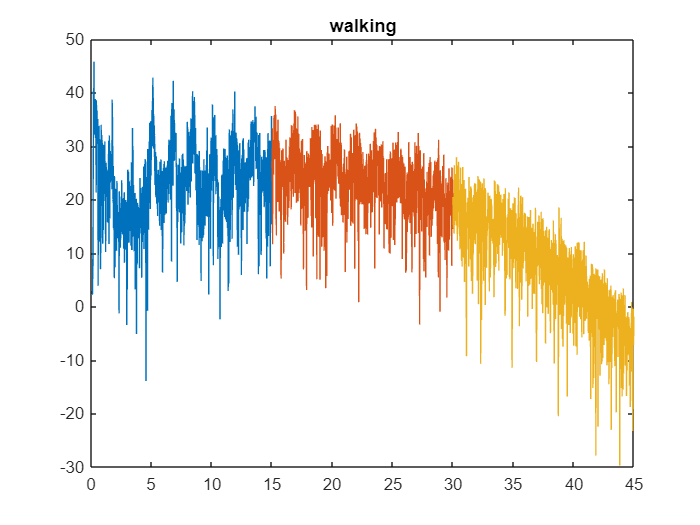

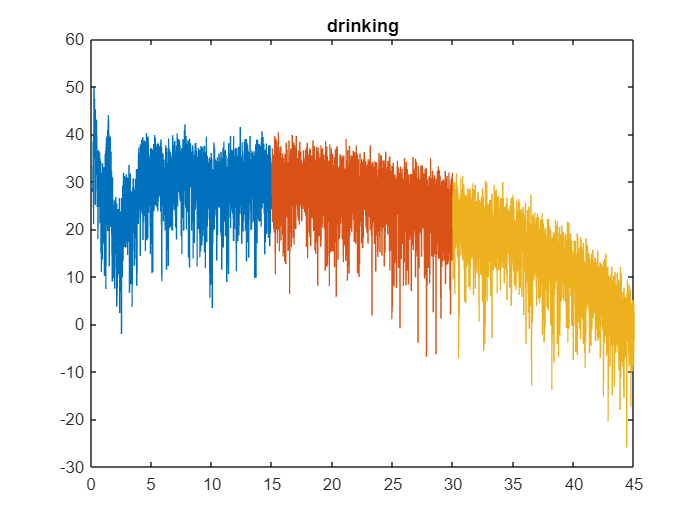

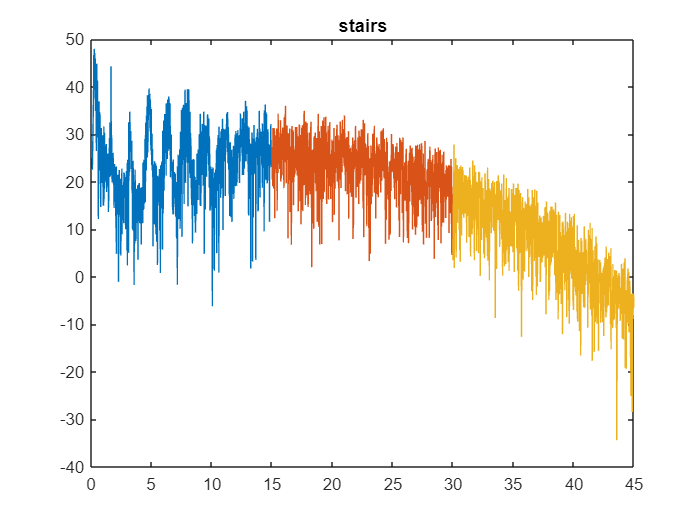

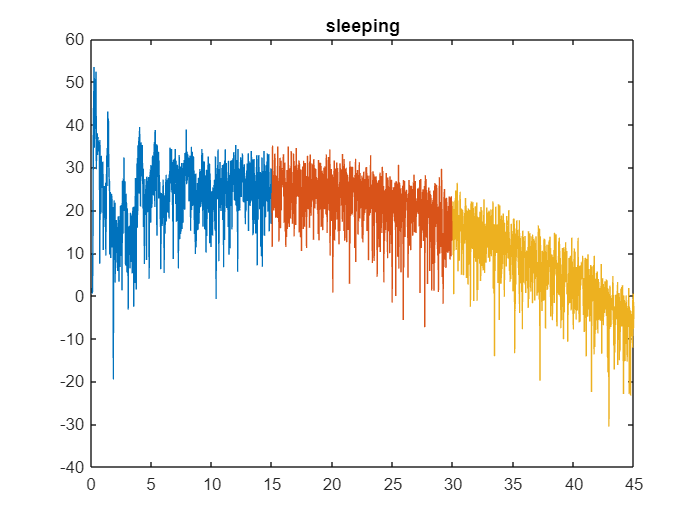

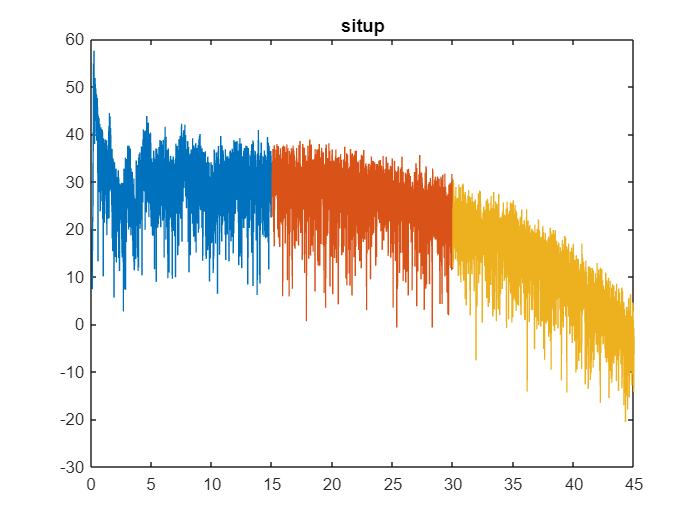

close all

for i = 1:size(task,2)
    DELTAF = length(freq_task{i,1}{1,:})/FS;
    FREQ_delta01_15 = [0.1:1/DELTAF:15];
    k0115 = length(FREQ_delta01_15);
    VX_01_15 = VX_taskF{:,i}(1:k0115);
    VX_01_15s{i,1} = VX_01_15;
    VX_01_15 = 20*log10(abs(VX_01_15));
    
    FREQ_delta15_30 = [15:1/DELTAF:30];
    k15_30 = length(FREQ_delta15_30);
    VX_15_30 = VX_taskF{:,i}(k0115:k0115+k15_30-1);
    VX_15_30s{i,1} = VX_15_30;
    VX_15_30 = 20*log10(abs(VX_15_30));
    
    FREQ_delta30_45 = [30:1/DELTAF:45];
    k30_45 = length(FREQ_delta30_45);
    VX_30_45 = VX_taskF{:,i}(k0115+k15_30:k0115+k15_30+k30_45-1);
    VX_30_45s{i,1} = VX_30_45;
    VX_30_45 = 20*log10(abs(VX_30_45));
    
    figure(i)
    plot(FREQ_delta01_15,VX_01_15)
    hold on
    plot(FREQ_delta15_30,VX_15_30)
    hold on
    plot(FREQ_delta30_45,VX_30_45)
    title(task(i))

end


%%
[RWS15_30,PWS15_30] = corrcoef(abs(VX_15_30s{1,1}),abs(VX_15_30s{4,1}))

RWS15_30 =     1.0000    0.1447
    0.1447    1.0000


PWS15_30 =     1.0000    0.0000
    0.0000    1.0000


[RWS01_15,PWS01_15] = corrcoef(abs(VX_01_15s{1,1}),abs(VX_01_15s{4,1}))

RWS01_15 =     1.0000    0.3502
    0.3502    1.0000


PWS01_15 =     1.0000    0.0000
    0.0000    1.0000


[RWS30_45,PWS30_45] = corrcoef(abs(VX_30_45s{1,1}),abs(VX_30_45s{4,1}))

RWS30_45 =     1.0000    0.5267
    0.5267    1.0000


PWS30_45 =     1.0000    0.0000
    0.0000    1.0000


%%
[RWSt15_30,PWSt15_30] = corrcoef(abs(VX_15_30s{1,1}),abs(VX_15_30s{3,1}));

RWSt15_30 =     1.0000    0.1807
    0.1807    1.0000


PWSt15_30 =     1.0000    0.0000
    0.0000    1.0000


[RWSt01_15,PWSt01_15] = corrcoef(abs(VX_01_15s{1,1}),abs(VX_01_15s{3,1}));

RWSt01_15 =     1.0000    0.2246
    0.2246    1.0000


PWSt01_15 =     1.0000    0.0000
    0.0000    1.0000


[RWSt30_45,PWSt30_45] = corrcoef(abs(VX_30_45s{1,1}),abs(VX_30_45s{3,1}));

RWSt30_45 =     1.0000    0.5283
    0.5283    1.0000


PWSt30_45 =     1.0000    0.0000
    0.0000    1.0000



%%
for i = 1:length(VX_30_45s{4,1})
    EW = sum(abs(VX_30_45s{4,1}(i).^2))
end

EW = 159.3531

EW = 9.0960

EW = 55.3403

EW = 32.7729

EW = 1.0862

EW = 32.9327

EW = 104.3713

EW = 64.1183

EW = 99.3740

EW = 93.2686

EW = 168.3766

EW = 20.3730

EW = 46.8980

EW = 185.1922

EW = 287.8006

EW = 45.7460

EW = 11.9130

EW = 13.3652

EW = 41.5251

EW = 97.5892

EW = 26.8473

EW = 438.9555

EW = 225.6860

EW = 22.4618

EW = 168.1957

EW = 3.7674

EW = 20.3359

EW = 8.4888

EW = 49.1739

EW = 77.9470

EW = 10.2729

EW = 9.8282

EW = 6.5983

EW = 40.6077

EW = 32.2495

EW = 113.0117

EW = 269.3501

EW = 78.8916

EW = 31.4513

EW = 37.7897

EW = 58.7688

EW = 36.5839

EW = 110.1648

EW = 3.1043

EW = 13.8926

EW = 69.3182

EW = 21.6804

EW = 11.5779

EW = 103.6792

EW = 71.3193

EW = 87.7928

EW = 40.5684

EW = 14.4924

EW = 3.0395

EW = 29.2810

EW = 17.1121

EW = 46.3160

EW = 25.5813

EW = 16.5066

EW = 85.5938

EW = 38.9724

EW = 19.2733

EW = 103.5855

EW = 193.2463

EW = 26.4970

EW = 82.3085

EW = 127.4026

EW = 77.9090

EW = 2.5934

EW = 98.6146

EW = 16.0525

EW = 31.7933

EW = 9.2434

EW = 50.6751

EW = 98.1315

EW = 32.1798

EW = 1.8253

EW = 27.0408

EW = 109.5207

EW = 16.9172

EW = 12.9441

EW = 5.2842

EW = 18.9674

EW = 70.1837

EW = 23.9963

EW = 103.0344

EW = 40.9071

EW = 80.6743

EW = 0.5582

EW = 4.2362

EW = 29.7215

EW = 142.4538

EW = 82.2590

EW = 44.7337

EW = 160.7132

EW = 94.9112

EW = 63.3374

EW = 13.2385

EW = 89.1338

EW = 12.3427

EW = 153.4568

EW = 98.6962

EW = 39.7575

EW = 114.2152

EW = 52.0980

EW = 0.7520

EW = 41.9910

EW = 21.1639

EW = 72.0991

EW = 7.5983

EW = 39.0237

EW = 13.5548

EW = 81.9023

EW = 123.0185

EW = 72.3570

EW = 6.2873

EW = 16.0762

EW = 22.9434

EW = 69.7260

EW = 99.0195

EW = 150.6959

EW = 16.8419

EW = 0.7653

EW = 24.7943

EW = 71.0773

EW = 1.3443

EW = 37.0127

EW = 42.0917

EW = 7.2527

EW = 10.8306

EW = 68.6704

EW = 13.7758

EW = 12.4685

EW = 26.6380

EW = 17.0061

EW = 5.5727

EW = 29.0448

EW = 91.9441

EW = 63.9085

EW = 2.2301

EW = 3.8911

EW = 2.8593

EW = 118.9633

EW = 9.6047

EW = 74.3591

EW = 103.0587

EW = 47.9754

EW = 5.0122

EW = 39.7017

EW = 18.2573

EW = 18.7743

EW = 54.9041

EW = 4.5203

EW = 3.9598

EW = 41.5007

EW = 35.4771

EW = 78.8448

EW = 179.8948

EW = 28.2420

EW = 18.3393

EW = 3.4072

EW = 47.7431

EW = 28.4231

EW = 19.7633

EW = 44.0383

EW = 18.6739

EW = 38.9655

EW = 5.9410

EW = 10.2514

EW = 23.1683

EW = 52.4818

EW = 115.7477

EW = 18.4395

EW = 85.7314

EW = 66.3891

EW = 13.2521

EW = 81.1957

EW = 15.3221

EW = 49.4364

EW = 91.9595

EW = 7.7245

EW = 30.0112

EW = 55.7181

EW = 98.7609

EW = 26.1467

EW = 21.4051

EW = 6.2661

EW = 11.2391

EW = 52.5395

EW = 14.6181

EW = 10.9177

EW = 57.3429

EW = 103.5587

EW = 83.5213

EW = 8.4173

EW = 28.7428

EW = 37.2442

EW = 11.6240

EW = 62.7997

EW = 77.0277

EW = 18.3884

EW = 64.8916

EW = 160.3134

EW = 49.5296

EW = 1.4749

EW = 3.8725

EW = 13.0586

EW = 1.1372

EW = 13.8541

EW = 47.1790

EW = 0.0386

EW = 6.8755

EW = 23.3857

EW = 3.8030

EW = 23.9972

EW = 17.6992

EW = 120.3072

EW = 14.5013

EW = 24.4349

EW = 35.8261

EW = 44.2335

EW = 9.9491

EW = 24.2001

EW = 25.2021

EW = 46.8658

EW = 44.6888

EW = 19.0548

EW = 38.9309

EW = 1.9813

EW = 12.6693

EW = 137.8392

EW = 29.4095

EW = 43.4064

EW = 8.2263

EW = 0.2706

EW = 11.3469

EW = 1.8554

EW = 128.3923

EW = 40.1772

EW = 23.0698

EW = 61.7405

EW = 24.6027

EW = 53.9676

EW = 1.9166

EW = 40.8169

EW = 2.6488

EW = 75.0471

EW = 8.4310

EW = 4.2362

EW = 33.8076

EW = 43.7293

EW = 5.6456

EW = 17.9685

EW = 43.8273

EW = 84.2119

EW = 61.2550

EW = 54.2921

EW = 23.9810

EW = 34.6797

EW = 3.9250

EW = 0.9461

EW = 50.5817

EW = 20.8033

EW = 24.3191

EW = 8.8896

EW = 10.2095

EW = 21.7730

EW = 17.4229

EW = 31.3519

EW = 4.8227

EW = 6.4382

EW = 23.2312

EW = 73.3244

EW = 15.6371

EW = 59.1445

EW = 43.5718

EW = 27.1338

EW = 13.4699

EW = 7.4542

EW = 30.6442

EW = 22.3185

EW = 32.6613

EW = 99.9100

EW = 18.1589

EW = 31.7659

EW = 8.2282

EW = 3.7285

EW = 15.3307

EW = 15.0456

EW = 2.1323

EW = 5.7264

EW = 14.5870

EW = 2.4214

EW = 20.3186

EW = 8.2474

EW = 48.0359

EW = 13.9902

EW = 19.1575

EW = 32.8509

EW = 17.0839

EW = 17.9168

EW = 5.1783

EW = 6.4568

EW = 2.4126

EW = 1.2766

EW = 3.6160

EW = 61.3946

EW = 30.2745

EW = 38.0905

EW = 64.1726

EW = 36.8693

EW = 39.0454

EW = 0.0452

EW = 0.4451

EW = 0.4705

EW = 0.7350

EW = 29.0960

EW = 1.7665

EW = 2.1533

EW = 28.6354

EW = 20.3990

EW = 35.4751

EW = 7.8418

EW = 57.8999

EW = 20.1171

EW = 22.1883

EW = 13.4369

EW = 17.1922

EW = 34.9338

EW = 19.5757

EW = 9.5607

EW = 4.4228

EW = 22.9894

EW = 3.0135

EW = 9.5958

EW = 1.1458

EW = 58.2145

EW = 0.3940

EW = 25.0403

EW = 12.3672

EW = 22.5987

EW = 2.2941

EW = 1.9712

EW = 10.8079

EW = 10.9264

EW = 5.5997

EW = 9.5415

EW = 3.0309

EW = 1.2058

EW = 6.0229

EW = 25.4156

EW = 0.1647

EW = 17.0575

EW = 32.9093

EW = 19.9696

EW = 17.1181

EW = 24.0473

EW = 2.0089

EW = 18.6295

EW = 18.4338

EW = 7.6897

EW = 9.1123

EW = 16.1158

EW = 11.1344

EW = 24.8840

EW = 12.3972

EW = 1.8280

EW = 2.7060

EW = 1.1688

EW = 10.6920

EW = 9.2363

EW = 7.0896

EW = 3.5942

EW = 11.4530

EW = 6.0997

EW = 8.9381

EW = 2.2617

EW = 7.6307

EW = 1.4534

EW = 8.8719

EW = 13.8645

EW = 0.5238

EW = 32.3302

EW = 2.6773

EW = 0.8351

EW = 19.3467

EW = 24.3517

EW = 6.0481

EW = 28.9718

EW = 12.8243

EW = 25.0714

EW = 8.6807

EW = 5.6441

EW = 3.6921

EW = 1.2417

EW = 6.1631

EW = 7.6293

EW = 7.3876

EW = 2.7418

EW = 24.6387

EW = 3.1441

EW = 9.3593

EW = 0.6673

EW = 26.9058

EW = 10.8145

EW = 6.0354

EW = 4.5465

EW = 11.0415

EW = 16.1657

EW = 21.4310

EW = 3.3563

EW = 19.8237

EW = 1.9996

EW = 3.4816

EW = 0.7768

EW = 17.4035

EW = 3.3419

EW = 2.5083

EW = 5.1937

EW = 4.8334

EW = 24.6955

EW = 10.7919

EW = 3.5886

EW = 3.3028

EW = 6.1402

EW = 1.0051

EW = 5.9120

EW = 1.1466

EW = 1.6567

EW = 1.1769

EW = 2.2151

EW = 9.8190

EW = 43.8546

EW = 1.4203

EW = 2.7639

EW = 8.6840

EW = 0.8357

EW = 30.2422

EW = 37.2600

EW = 1.1105

EW = 0.0104

EW = 4.4690

EW = 24.2359

EW = 7.9531

EW = 5.1813

EW = 1.3936

EW = 5.1235

EW = 1.6144

EW = 1.2529

EW = 1.1085

EW = 0.4440

EW = 1.4672

EW = 11.3233

EW = 6.2337

EW = 10.5602

EW = 1.6830

EW = 8.8344

EW = 3.4126

EW = 0.7625

EW = 10.6570

EW = 7.5996

EW = 21.7468

EW = 14.5675

EW = 0.7987

EW = 17.7105

EW = 20.6966

EW = 3.2589

EW = 10.8847

EW = 0.1711

EW = 1.7894

EW = 5.8552

EW = 1.8478

EW = 10.6442

EW = 4.8806

EW = 2.6130

EW = 11.8521

EW = 15.6769

EW = 1.3823

EW = 1.4721

EW = 3.9858

EW = 6.8276

EW = 4.1375

EW = 1.8006

EW = 4.7018

EW = 3.6320

EW = 17.2491

EW = 7.7457

EW = 19.8438

EW = 5.9373

EW = 11.1535

EW = 7.5613

EW = 23.9964

EW = 2.9593

EW = 0.9343

EW = 13.0626

EW = 0.3277

EW = 0.9795

EW = 3.9387

EW = 2.3719

EW = 4.8819

EW = 2.9546

EW = 9.2797

EW = 2.6291

EW = 0.2693

EW = 2.8937

EW = 8.1689

EW = 2.2251

EW = 1.0094

EW = 2.6580

EW = 3.6566

EW = 3.3465

EW = 11.6877

EW = 0.6757

EW = 1.4548

EW = 29.9147

EW = 2.9335

EW = 7.0283

EW = 4.9778

EW = 13.0200

EW = 4.3746

EW = 5.4711

EW = 27.5700

EW = 6.7444

EW = 6.2921

EW = 4.8174

EW = 0.2883

EW = 0.1946

EW = 1.1177

EW = 5.9493

EW = 1.7900

EW = 1.7586

EW = 3.5962

EW = 1.1394

EW = 1.5197

EW = 6.4640

EW = 18.6150

EW = 1.0476

EW = 1.9659

EW = 22.8622

EW = 12.6016

EW = 10.7816

EW = 9.9439

EW = 0.9767

EW = 7.4337

EW = 1.0796

EW = 2.8595

EW = 0.1752

EW = 2.6831

EW = 3.2806

EW = 2.6911

EW = 0.2683

EW = 5.2804

EW = 3.2395

EW = 2.9224

EW = 13.1149

EW = 2.9820

EW = 5.7457

EW = 4.8652

EW = 1.1368

EW = 0.0971

EW = 1.2205

EW = 13.5746

EW = 6.2007

EW = 0.4092

EW = 6.3338

EW = 1.5884

EW = 7.5960

EW = 7.2366

EW = 2.7219

EW = 5.6530

EW = 17.7674

EW = 2.5553

EW = 5.4754

EW = 2.1437

EW = 2.1315

EW = 10.9126

EW = 10.9276

EW = 1.0683

EW = 1.0931

EW = 1.7981

EW = 1.2867

EW = 0.0846

EW = 1.0656

EW = 0.6076

EW = 1.1069

EW = 2.1022

EW = 3.0219

EW = 7.6710

EW = 5.4709

EW = 7.2222

EW = 1.3492

EW = 0.6742

EW = 5.7198

EW = 6.7619

EW = 8.6166

EW = 3.6614

EW = 5.0625

EW = 1.0161

EW = 0.4624

EW = 3.5668

EW = 0.8702

EW = 22.8081

EW = 2.0278

EW = 2.7129

EW = 6.4072

EW = 2.6097

EW = 1.3483

EW = 0.3620

EW = 2.3160

EW = 0.1638

EW = 1.2457

EW = 0.8790

EW = 7.0307

EW = 0.3910

EW = 12.7038

EW = 7.4540

EW = 2.7211

EW = 1.8530

EW = 10.7346

EW = 0.4791

EW = 3.2181

EW = 1.3694

EW = 3.7706

EW = 0.2805

EW = 1.0989

EW = 4.7028

EW = 2.1079

EW = 1.7614

EW = 4.1988

EW = 0.4517

EW = 2.5872

EW = 5.2252

EW = 1.3251

EW = 22.8382

EW = 1.9770

EW = 0.9742

EW = 4.9827

EW = 1.4419

EW = 0.3568

EW = 0.2427

EW = 0.4778

EW = 3.2027

EW = 3.4174

EW = 0.2513

EW = 5.1411

EW = 1.7531

EW = 1.6771

EW = 2.3685

EW = 3.7884

EW = 3.7031

EW = 6.0800

EW = 4.8088

EW = 2.5349

EW = 2.5164

EW = 2.7418

EW = 3.2218

EW = 8.5866

EW = 4.5293

EW = 1.5530

EW = 0.9717

EW = 0.3527

EW = 2.5785

EW = 2.0701

EW = 1.8380

EW = 0.1418

EW = 0.3406

EW = 0.1548

EW = 1.9610

EW = 5.9282

EW = 7.7855

EW = 2.3790

EW = 7.1100

EW = 1.7480

EW = 1.3000

EW = 0.0387

EW = 1.2778

EW = 2.5298

EW = 1.7944

EW = 7.3122

EW = 0.5066

EW = 5.6425

EW = 0.5343

EW = 0.3223

EW = 9.3838

EW = 0.4874

EW = 0.6534

EW = 1.1823

EW = 4.2410

EW = 0.9404

EW = 2.9838

EW = 3.1590

EW = 2.9616

EW = 0.2507

EW = 2.8317

EW = 1.4982

EW = 0.3379

EW = 3.9485

EW = 5.2471

EW = 3.2021

EW = 1.0397

EW = 1.7406

EW = 0.0057

EW = 0.6116

EW = 2.4647

EW = 4.8998

EW = 0.9918

EW = 1.8476

EW = 1.8095

EW = 0.8009

EW = 1.0329

EW = 0.7468

EW = 0.8053

EW = 5.1871

EW = 0.6618

EW = 0.0433

EW = 8.6450

EW = 0.1718

EW = 0.1189

EW = 0.0633

EW = 2.2301

EW = 2.5312

EW = 0.2630

EW = 0.1572

EW = 0.4733

EW = 1.1667

EW = 0.2664

EW = 3.4276

EW = 0.4871

EW = 1.9159

EW = 1.7724

EW = 3.6766

EW = 0.4261

EW = 1.0632

EW = 0.1320

EW = 0.8399

EW = 2.4690

EW = 1.5642

EW = 0.4972

EW = 2.1127

EW = 0.9835

EW = 0.2761

EW = 0.4807

EW = 0.7474

EW = 1.5220

EW = 1.3157

EW = 1.0950

EW = 0.2621

EW = 0.8316

EW = 0.9040

EW = 0.9396

EW = 5.5516

EW = 0.5368

EW = 0.4434

EW = 0.0444

EW = 0.7468

EW = 0.3629

EW = 0.3238

EW = 2.5655

EW = 0.9141

EW = 0.6034

EW = 1.8755

EW = 0.2052

EW = 1.5952

EW = 0.7739

EW = 0.6583

EW = 1.0024

EW = 0.4266

EW = 0.3996

EW = 0.5589

EW = 2.1743

EW = 0.5619

EW = 1.4594

EW = 0.9123

EW = 0.4818

EW = 0.6386

EW = 1.0964

EW = 2.3920

EW = 0.3357

EW = 0.8544

EW = 2.3104

EW = 0.2003

EW = 1.1091

EW = 0.0361

EW = 0.2333

EW = 0.0160

EW = 1.4774

EW = 0.6880

EW = 0.6277

EW = 0.3108

EW = 8.6794e-04

EW = 1.0912

EW = 1.0648

EW = 0.1653

EW = 0.2151

EW = 1.7204

EW = 1.1102

EW = 0.7930

EW = 0.4274

EW = 0.3757

EW = 0.1865

EW = 0.4083

EW = 0.8789

EW = 0.5671

EW = 0.5781

EW = 0.5196

EW = 0.7906

EW = 1.0537

EW = 0.4536

EW = 0.6788

EW = 2.8826

EW = 0.9324

EW = 0.2797

EW = 1.0436

EW = 0.0677

EW = 0.2969

EW = 0.3283

EW = 0.0190

EW = 0.5723

EW = 0.4752

EW = 0.0466

EW = 0.1516

EW = 0.3983

EW = 0.2121

EW = 0.7336

EW = 1.0519

EW = 0.4949

EW = 0.2826

EW = 0.5822

EW = 0.3201

EW = 0.8452

EW = 1.0168

EW = 1.3344

EW = 0.8906

EW = 2.0900

EW = 0.0243

EW = 0.5639

EW = 0.4672

EW = 0.1995

EW = 0.3839

EW = 0.3134

EW = 1.1620

EW = 0.8882

EW = 0.0313

EW = 0.3326

EW = 0.2580

EW = 0.0525

EW = 0.3314

EW = 0.1439

EW = 0.7666

EW = 0.3630

EW = 1.4692

EW = 0.6956

EW = 0.1907

EW = 0.3318

EW = 1.6117

EW = 0.8653

EW = 0.2408

EW = 0.5992

EW = 1.7746

EW = 0.1907

EW = 0.6599

EW = 0.2232

EW = 0.0259

EW = 0.0051

EW = 1.0187

EW = 0.7935

EW = 0.5308

EW = 0.7981

EW = 0.1522

EW = 0.6946

EW = 0.0295

EW = 0.1496

EW = 0.4553

EW = 0.1793

EW = 0.0742

EW = 0.1816

EW = 1.0277

EW = 0.3696

EW = 0.2540

EW = 0.2577

EW = 0.5795

EW = 0.0290

EW = 0.0562

EW = 0.3775

EW = 0.3701

EW = 0.4026

EW = 0.1863

EW = 0.5266

EW = 0.4280

EW = 1.5272

EW = 0.6476

EW = 0.4769

EW = 0.0052

EW = 0.5331

EW = 0.1626

EW = 0.1575

EW = 0.1292

EW = 0.0496

EW = 0.0047

EW = 0.4534

EW = 0.3386

EW = 0.1106

EW = 0.2689

EW = 0.3818

EW = 0.2548

EW = 0.2316

EW = 0.2141

EW = 0.1681

EW = 0.1691

EW = 0.0608

EW = 0.8247

EW = 0.5980

EW = 1.1254

EW = 0.1689

EW = 0.7317

EW = 0.2759


powbp30_45w = bandpower(VX_30_45s{1,1},FS,[30 45])

powbp30_45w = 1.9761

powbp15_30w = bandpower(VX_30_45s{1,1},FS,[15 30])

powbp15_30w = 2.3863

powbp01_15w = bandpower(VX_30_45s{1,1},FS,[1 15])

powbp01_15w = 2.3204


powbp30_45st = bandpower(VX_30_45s{3,1},FS,[30 45])

powbp30_45st = 1.7792

powbp15_30st = bandpower(VX_30_45s{3,1},FS,[15 30])

powbp15_30st = 1.7411

powbp01_15st = bandpower(VX_30_45s{3,1},FS,[1 15])

powbp01_15st = 1.4356

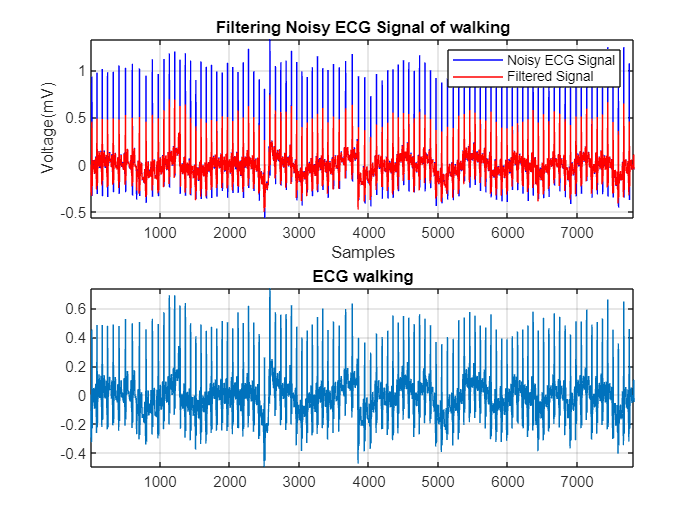

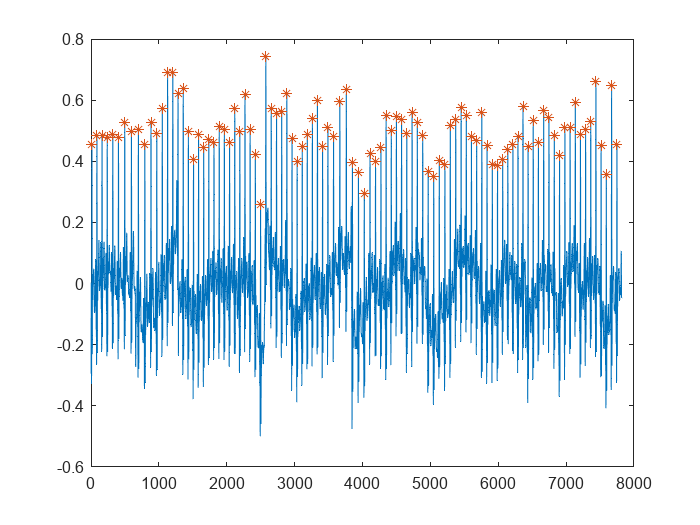

HR_ECG = 97.7089

RR_demean =   -38.5842
  -22.9592
  -22.9592
   23.9158
   39.5408
  102.0408
  156.7283
  180.1658
  125.4783
   94.2283


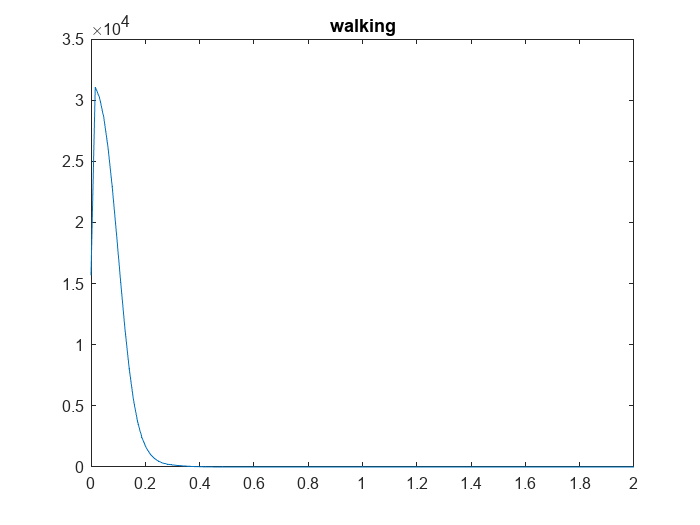

aLF = 1.7649e+03

aHF = 214.9305

TP = 2.0859e+03

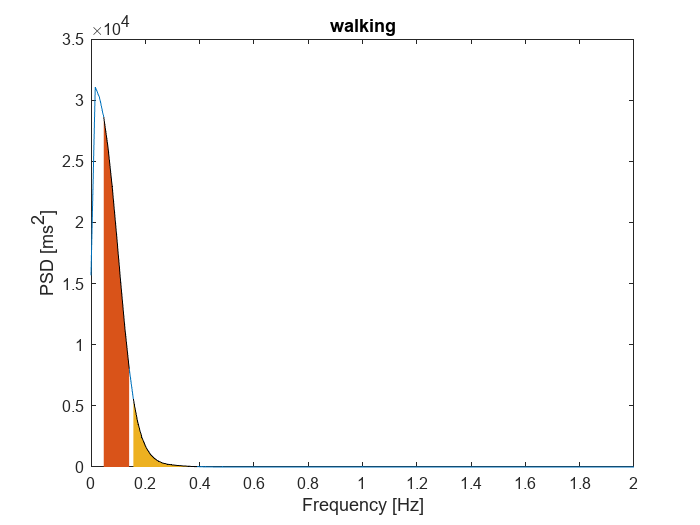

LFHF_ratio_ECG = 8.2114

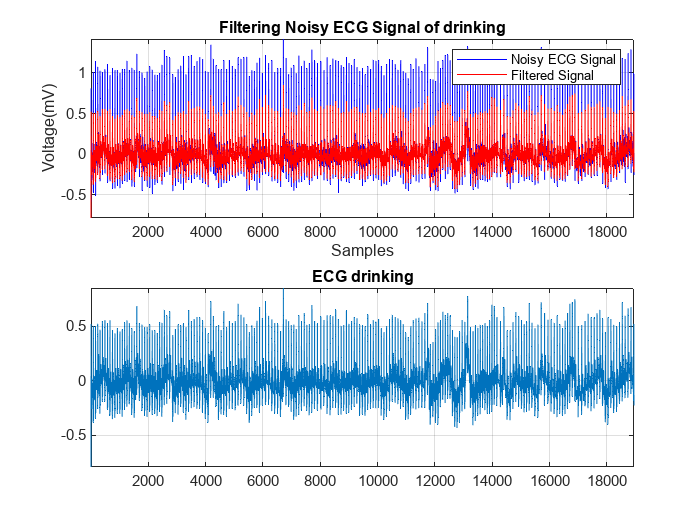

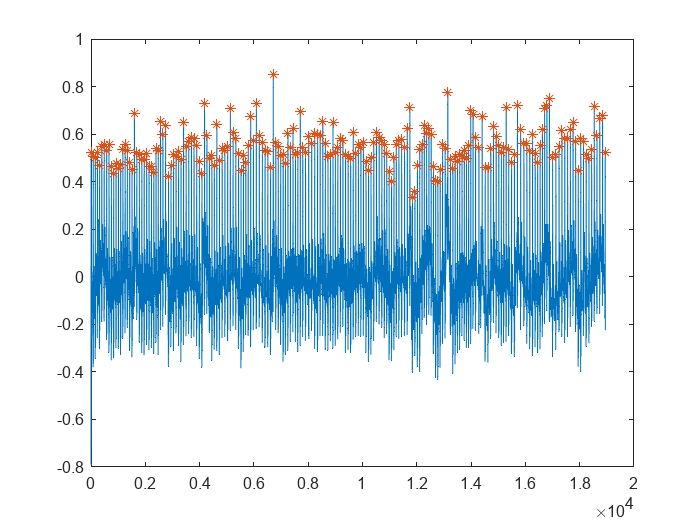

HR_ECG = 82.2701

RR_demean =  -142.1797
 -134.3672
 -126.5547
 -110.9297
  -95.3047
  -48.4297
  -24.9922
  -71.8672
  -48.4297
  -64.0547


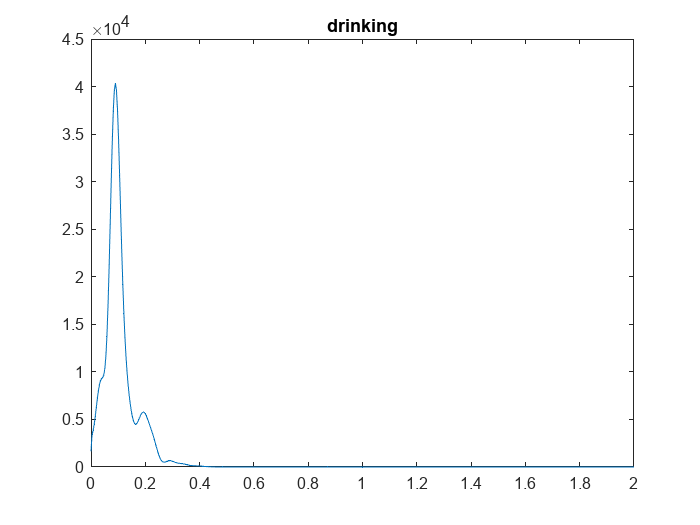

aLF = 2.3653e+03

aHF = 506.7464

TP = 2.8502e+03

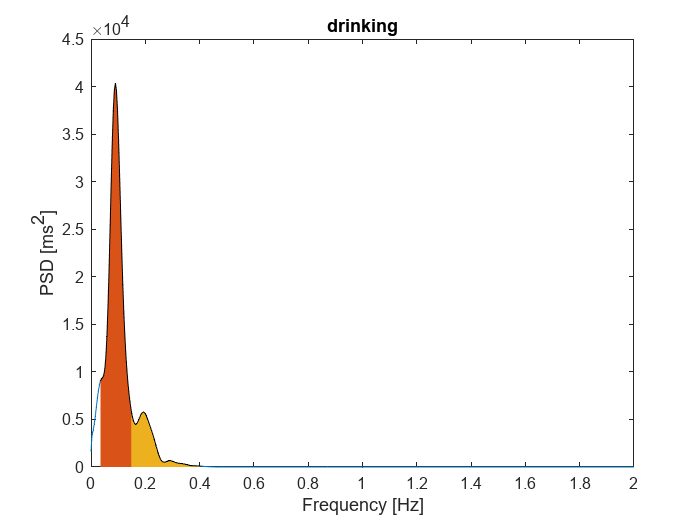

LFHF_ratio_ECG = 4.6675

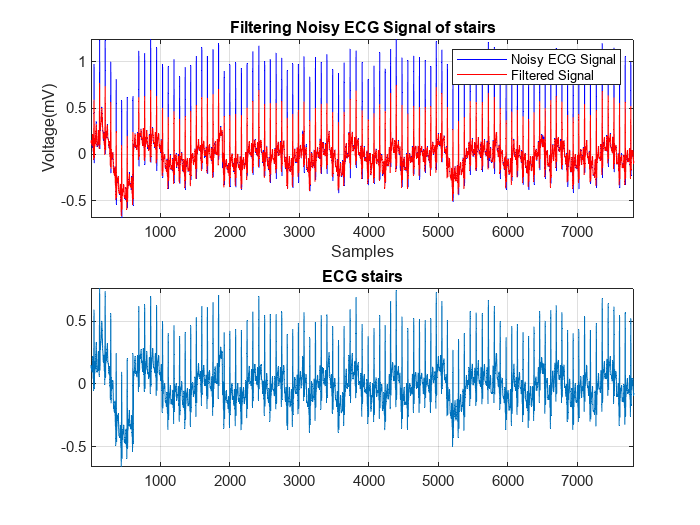

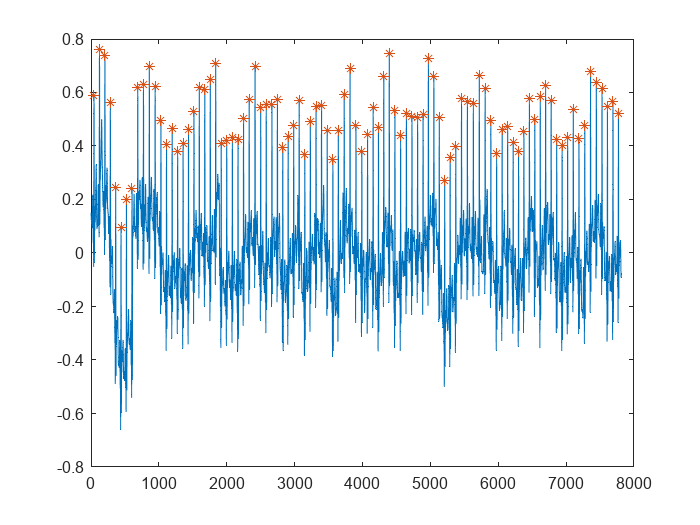

HR_ECG = 93.5129

RR_demean =    -9.3916
  -17.2041
  -17.2041
  -25.0166
  -32.8291
  -17.2041
   -1.5791
   21.8584
   14.0459
   37.4834


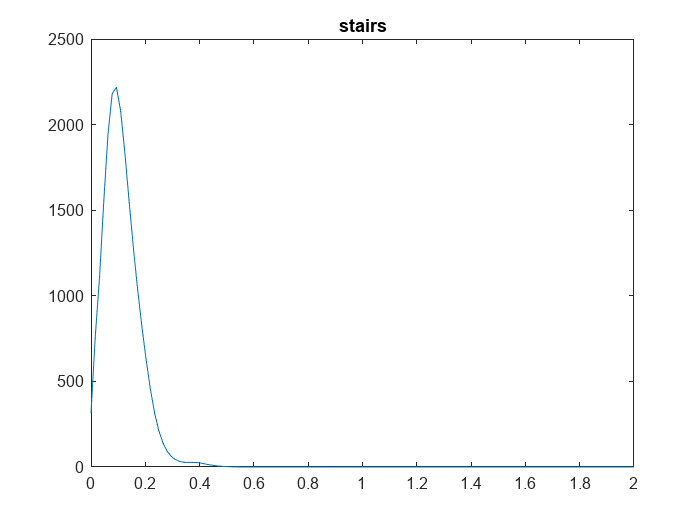

aLF = 184.3413

aHF = 71.1873

TP = 277.5986

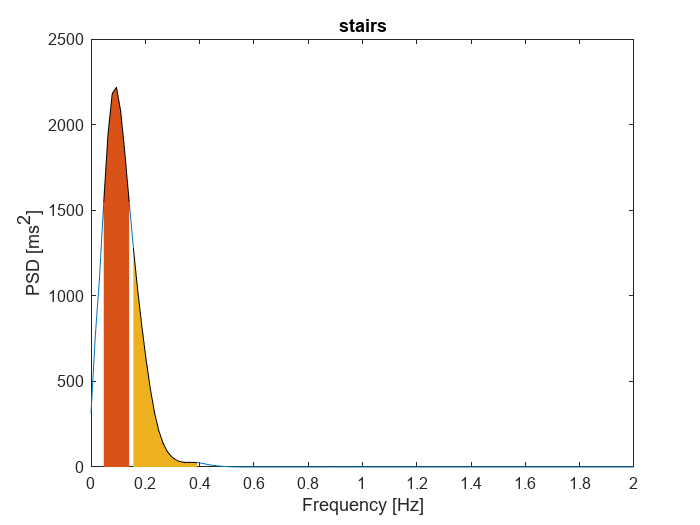

LFHF_ratio_ECG = 2.5895

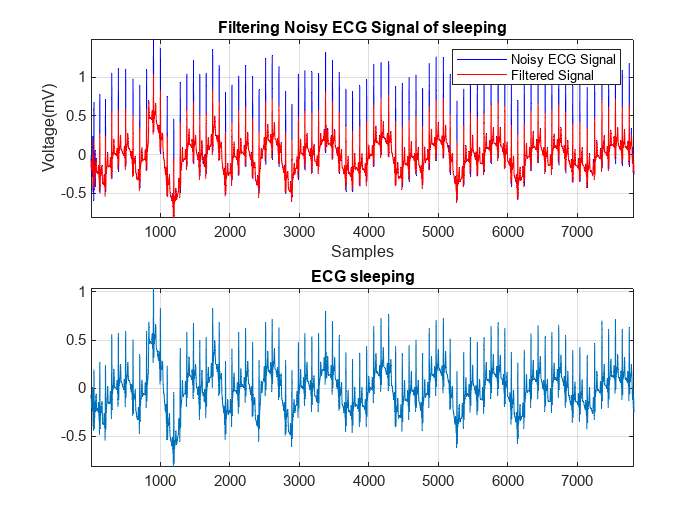

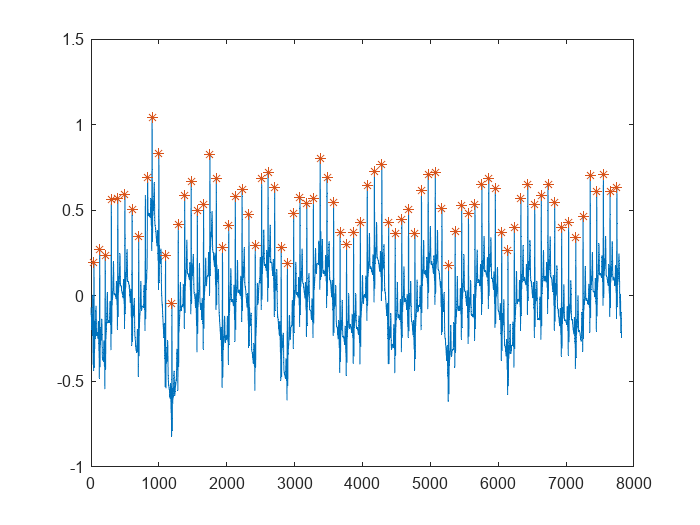

HR_ECG = 79.1897

RR_demean =  -105.6171
 -121.2421
  -58.7421
  -19.6796
   58.4454
   66.2579
   -4.0546
  261.5704
 -246.2421
   19.3829


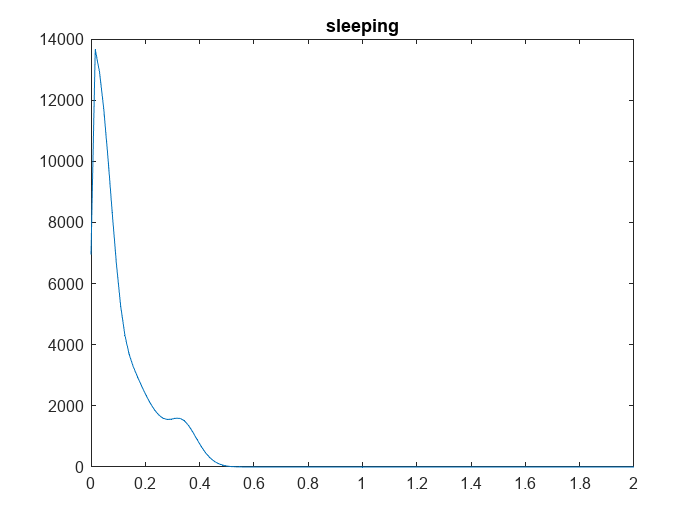

aLF = 661.2441

aHF = 430.4238

TP = 1.1460e+03

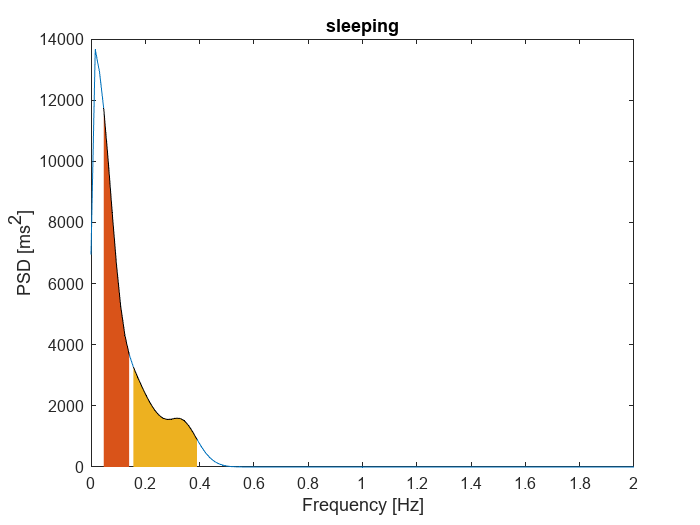

LFHF_ratio_ECG = 1.5363

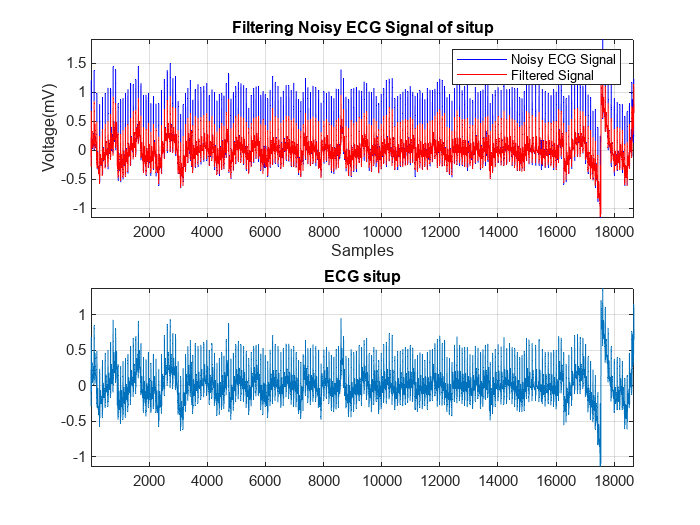

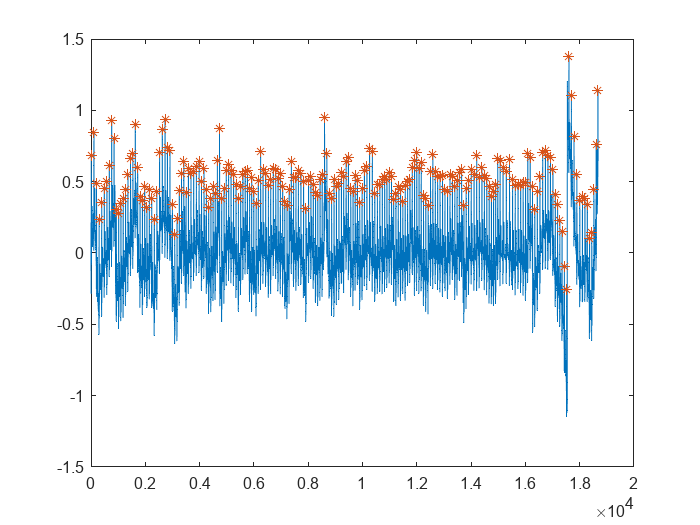

HR_ECG = 87.3837

RR_demean =    82.4570
   43.3945
   59.0195
   66.8320
   51.2070
   51.2070
   -3.4805
   -3.4805
  -11.2930
  -26.9180


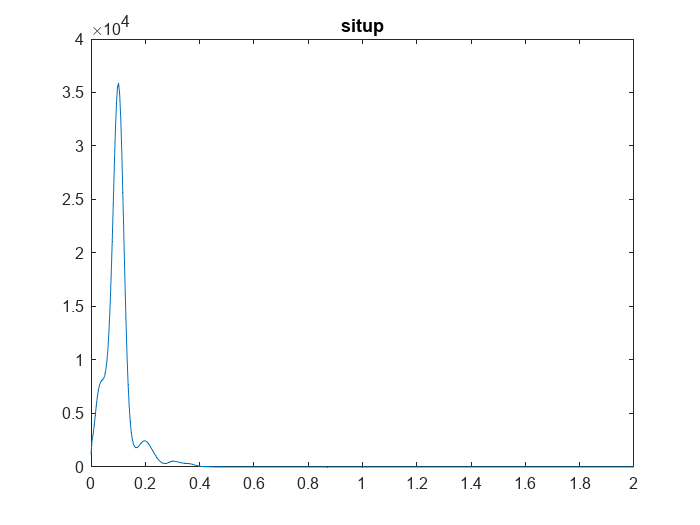

aLF = 2.0748e+03

aHF = 247.7032

TP = 2.3113e+03

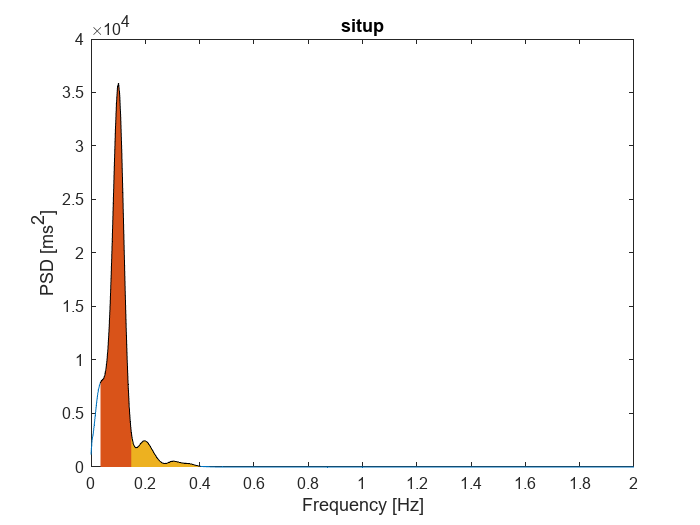

LFHF_ratio_ECG = 8.3763


%%
for i = 1:size(task,2)
    tt_task = [1 : length(VX_task{1,i})];
    
    % PULIZIA DEL SEGNALE
    smoothECG = sgolayfilt(VX_task{1,i},7,21);
    
    figure()
    subplot(211)
    plot(tt_task,VX_task{1,i},'b',tt_task,smoothECG,'r')
    grid on
    axis tight
    xlabel('Samples')
    ylabel('Voltage(mV)')
    legend('Noisy ECG Signal','Filtered Signal')
    title('Filtering Noisy ECG Signal of ' + task(i));
    
    subplot(212)
    plot(tt_task,smoothECG)
    grid on
    axis tight
    title('ECG ' + task(i))

    [R_pks,R_locs] = findpeaks(smoothECG,'MinPeakDistance',0.5 * FS); 
    figure
    plot(tt_task,smoothECG)
    hold on
    plot(tt_task(R_locs),smoothECG(R_locs),'*')
    
    RR_ist = (R_locs(2:end) - R_locs(1:end-1)) * 1/FS;
    t_RR_ist = cumsum(RR_ist); 
    t_RR_ist = t_RR_ist - t_RR_ist(1) * ones(size(t_RR_ist(1)));
    HR_ECG = mean(60 ./ RR_ist)
    SDNN_ECG = std(RR_ist) *1000;
    RMSSD_ECG = sqrt(mean((RR_ist(2:end) - RR_ist(1:end-1)).^2)) * 1000;
    RR_ms = RR_ist * 1000; 
    RR_demean = RR_ms - mean(RR_ms)*ones(size(RR_ms))
    RR_ms = RR_ist * 1000; 
    RR_demean = RR_ms - mean(RR_ms)*ones(size(RR_ms));
    
    % Detrend
    RR_detrend = detrend(RR_demean,'linear');
    
    % Interpolation
    F_resample = 4; 
    T_resample = 1/F_resample; 
    t_res = t_RR_ist(1):T_resample:t_RR_ist(end); 
    RR_ist_resample = interp1(t_RR_ist,RR_detrend,t_res);

    % High pass filter
    ordr     = 6;
    ft       = 0.02; %[Hz] Cutoff frequency
    Wn_HP    = ft/(F_resample/2); %Normalized cutoff frequency
    [b, a]   = butter(ordr,Wn_HP,'high');
    RR_HP    = filtfilt(b,a,RR_ist_resample);
    
    % Low pass filter
    ordr     = 6;
    ft       = 0.4; %[Hz] Cutoff frequency
    Wn_LP    = ft/(F_resample/2); %Normalized cutoff frequency
    [b, a]   = butter(ordr,Wn_LP);
    RR_filt  = filtfilt(b,a,RR_HP);
    
    % window = 5*60*F_resample;
    L = length(RR_filt); 
    NFFT = 2^nextpow2(L); % Vollmer M. 2015 "A robust, simple and reliable measure of HRV using relative RR intervals"
    [PSD,F] = pwelch(RR_filt,[],[],NFFT,4);
    
    figure
    plot(F,PSD)
    title(task(i))
    
    LF = [0.04 0.15];
    HF = [0.15 0.4];
    
    iLF = (round(F,2) >= LF(1)) & (round(F,2) <= LF(2));
    aLF  = trapz(F(iLF),PSD(iLF))
    
    iHF = (round(F,2) >= HF(1)) & (round(F,2) <= HF(2));
    aHF  = trapz(F(iHF),PSD(iHF))
    
    i_TP = (round(F,2) >= LF(1)) & (round(F,2) <= HF(2)); 
    TP   = trapz(F(i_TP),PSD(i_TP))
    
    % Normalized values of the spectral bands
    nu_LF = aLF / TP * 100; 
    nu_HF = aHF / TP * 100;
    
    figure
    plot(F,PSD)
    xlabel('Frequency [Hz]'), ylabel('PSD [ms^2]')
    hold on 
    area(F(iLF),PSD(iLF))
    area(F(iHF),PSD(iHF))
    title(task(i))
    LFHF_ratio_ECG = aLF/aHF    
end

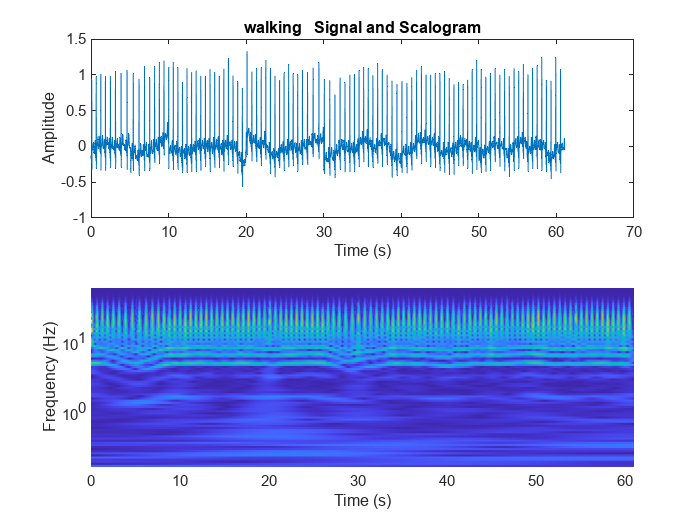

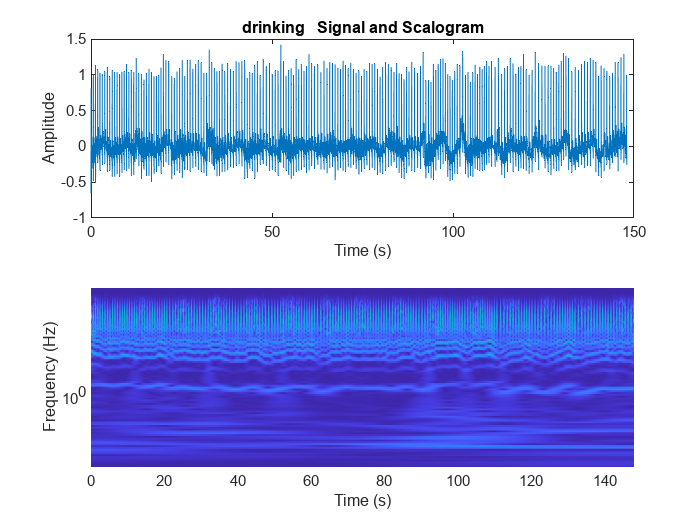

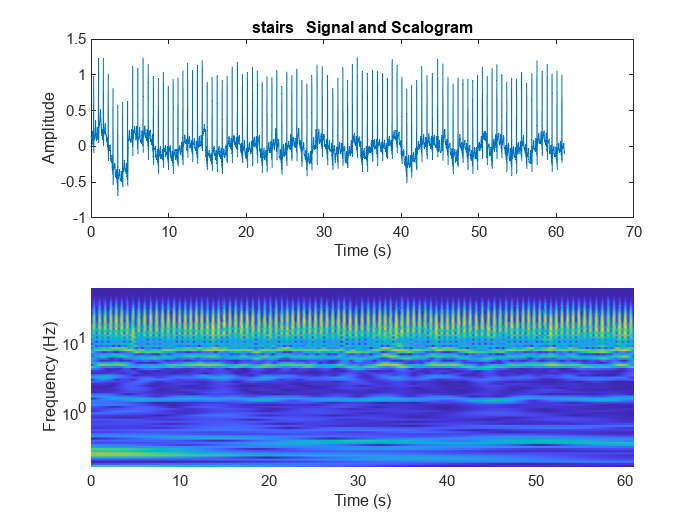

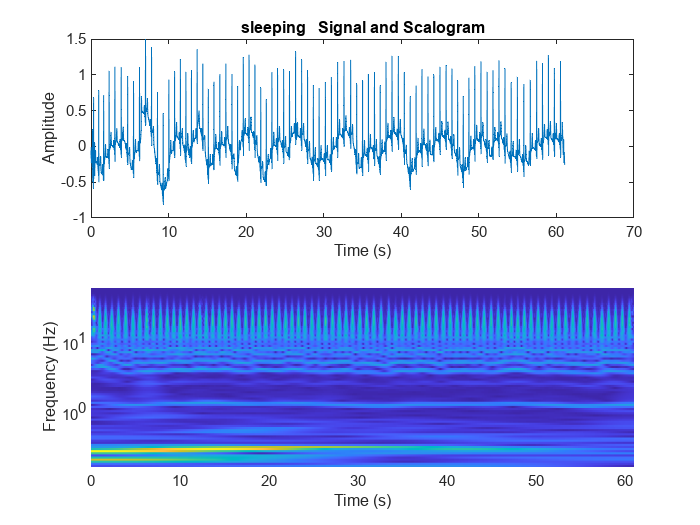

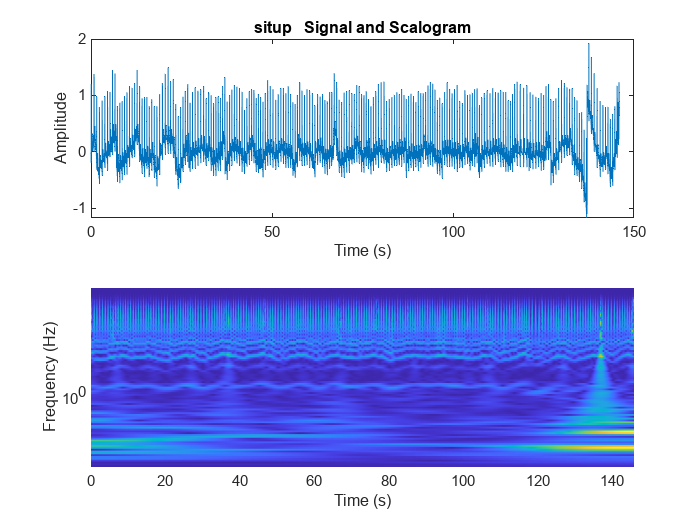


%%
for i = 1:size(task,2)
    time_t = [1:length(VX_task{i})];
    [cfs{i},freq_c] = cwt(VX_task{i},"bump",fps);
    tms = ((0:numel(time_t)-1)/fps);
    
    figure
    subplot(2,1,1)
    plot(tms,VX_task{i})
    title(task(i)+"   Signal and Scalogram")
    xlabel("Time (s)")
    ylabel("Amplitude")
    subplot(2,1,2)
    surface(tms,freq_c,abs(cfs{i}));
    axis tight
    shading flat
    colormap("default")
    xlabel("Time (s)")
    ylabel("Frequency (Hz)")
    set(gca,"yscale","log")
end